## Compares the size of a cluster of points in a spectrogram

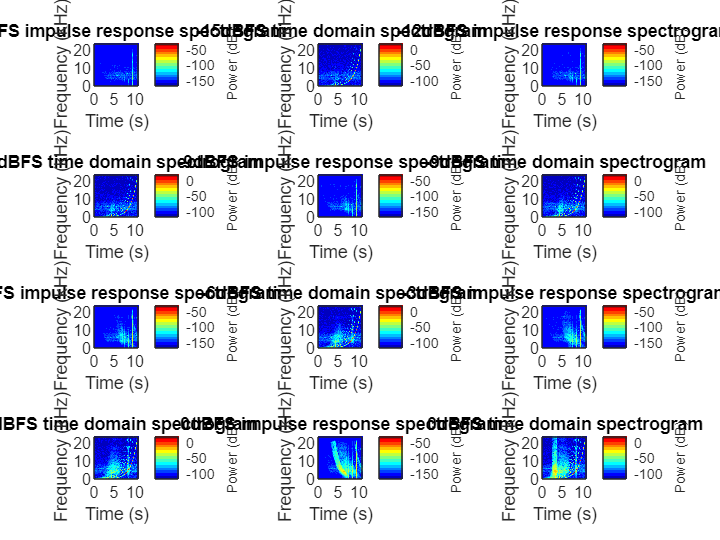

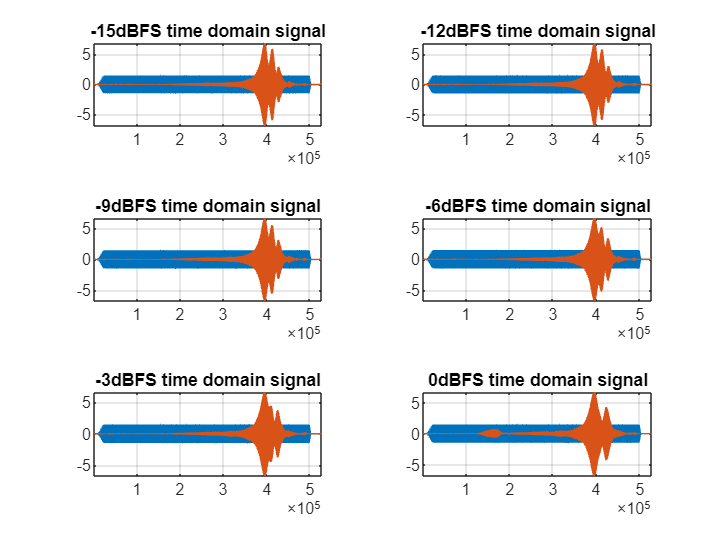

% skip this section if you already have the files in the directory
%plotDataForMathworks_mod  % run this line to generate the png files

% load in two files for comparisons
r6 = imread("reci-6dBFS.png");
r12 = imread("reci-12dBFS.png");


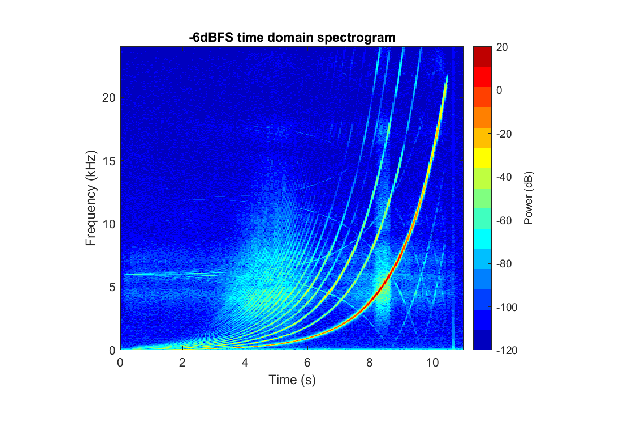

yyspec = r6;
imshow(yyspec)

### This section uses the colorThresholder app to create a mask function

The created mask function (createmask2) can then be used to segment out regions based on the pixel color.  In this case I had used the color bar on the right to select regions between 60-80dB. Ref:

https://www.mathworks.com/help/images/image-segmentation-using-the-color-thesholder-app.html

% skip this section if you do not need to create a new function
colorThresholder(yyspec)  % generate createMask function

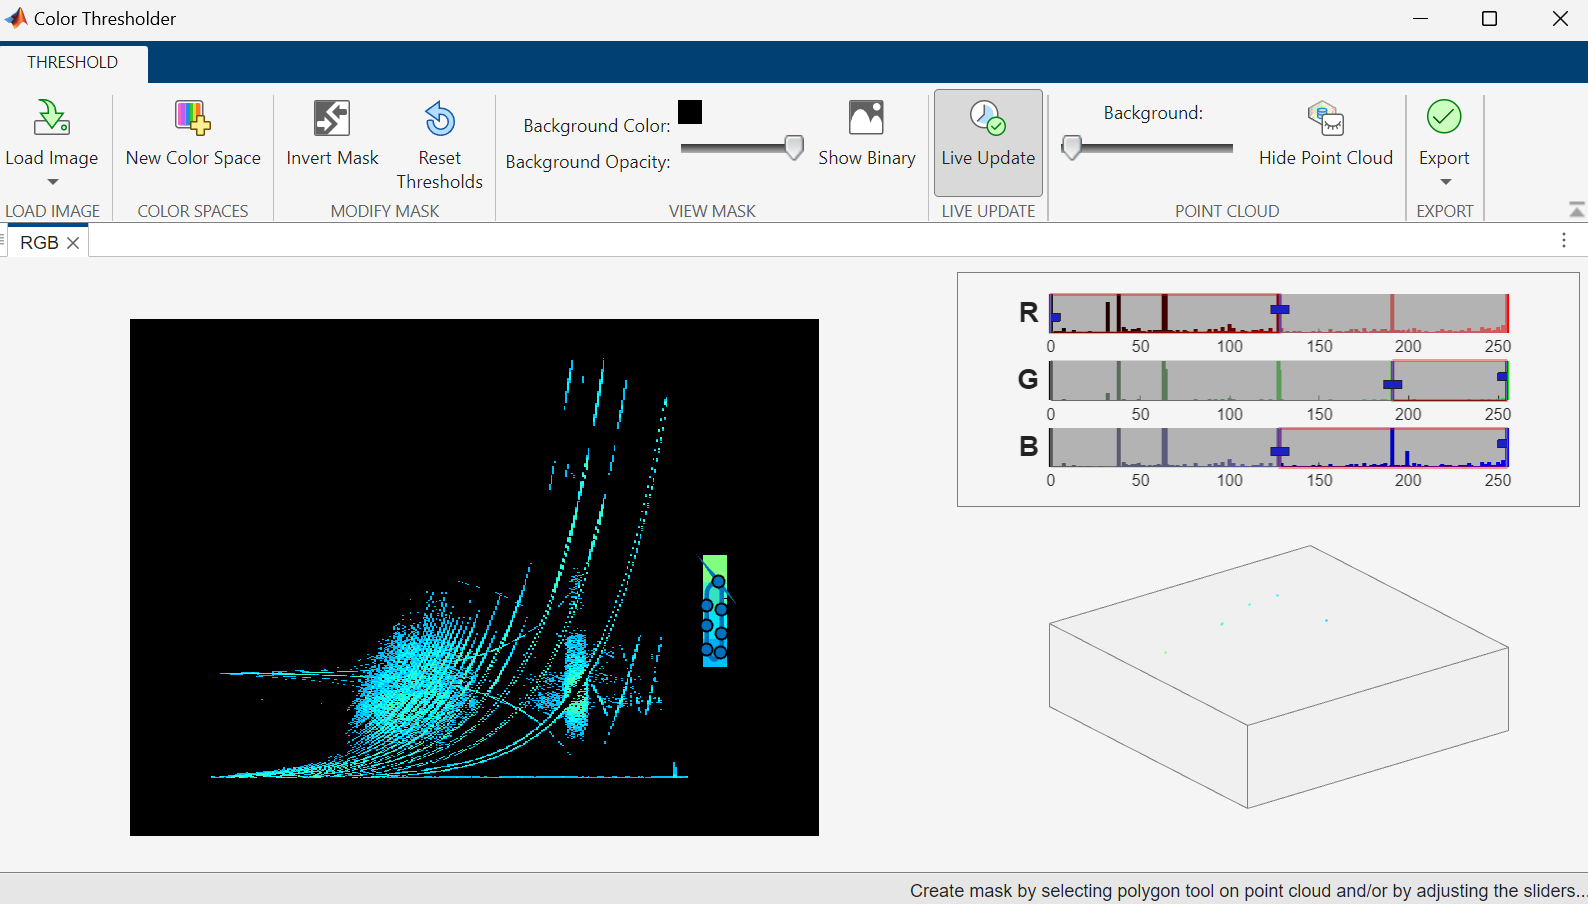

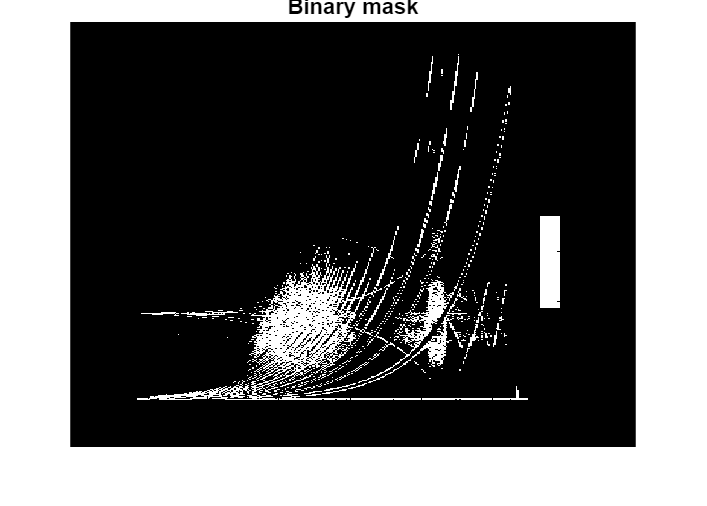

% using the mask function created from the previous segment, apply it to
% the image
 [BW,maskedRGBImage] = createMask2(yyspec);
 imshow(BW)
 title('Binary mask')

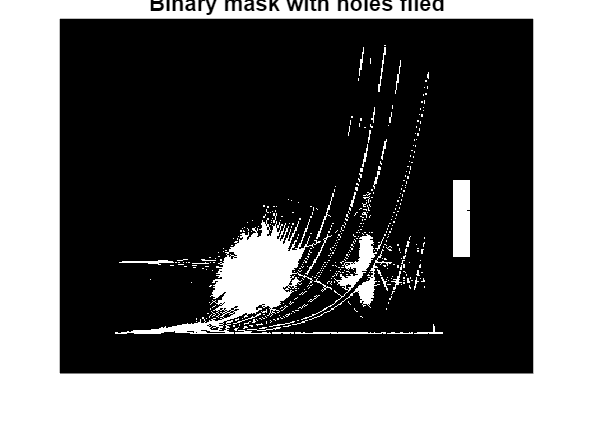

% use the imfill function to make the cluster points to become a solid
% piece
 FBW = imfill(BW,"holes");
imshow(FBW)
title('Binary mask with holes filed')

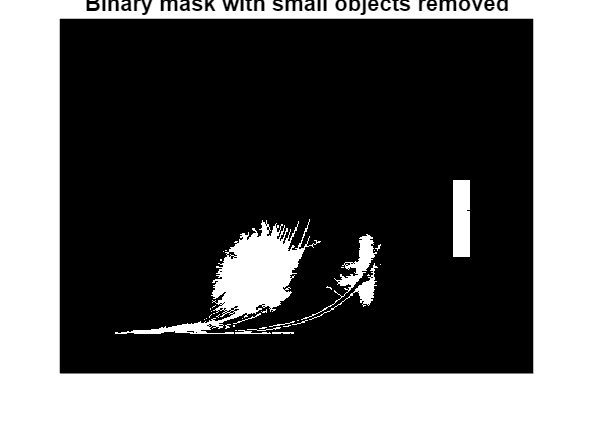

% use the bwareaopen function to remove objects smaller than 500 pixels
BW2 = bwareaopen(FBW,500);  % remove smaller obj
imshow(BW2) 
title('Binary mask with small objects removed')

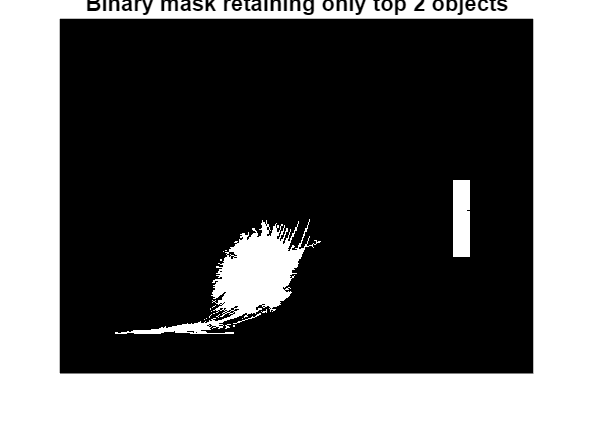

% Retaining only the largest 2 objects
BW_N = bwareafilt(BW2,2);  % retain N objects
imshow(BW_N)
title('Binary mask retaining only top 2 objects')

% finding the centroid of the object and measure the diameter of the first
% one
stats = regionprops("table",BW_N,"Centroid", ...
    "MajorAxisLength","MinorAxisLength")

stats = 2×3 table
        Centroid        MajorAxisLength    MinorAxisLength
    ________________    _______________    _______________

    351.01    481.61        285.76             133.22     
    742.97    370.45        163.93             35.749     


centers = stats.Centroid;

imshow(BW_N)
hold on
plot(centroids(:,1),centroids(:,2),'b*')

diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;
%Plot the circles.

viscircles(centers(1,:),radii(1))

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


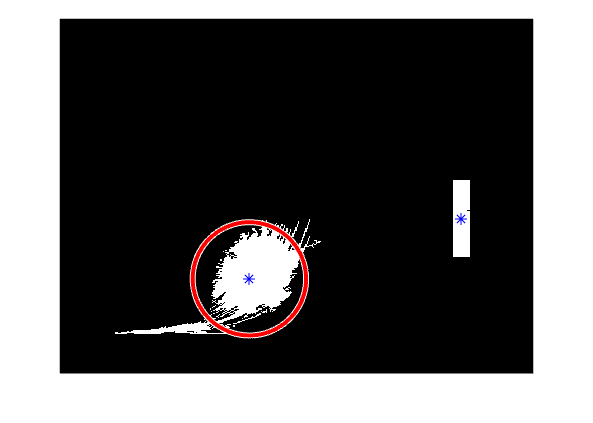

hold off

disp(['The radius of the cluster in reci-6dBFS is ' num2str(radii(1))])

The radius of the cluster in reci-6dBFS is 104.7457


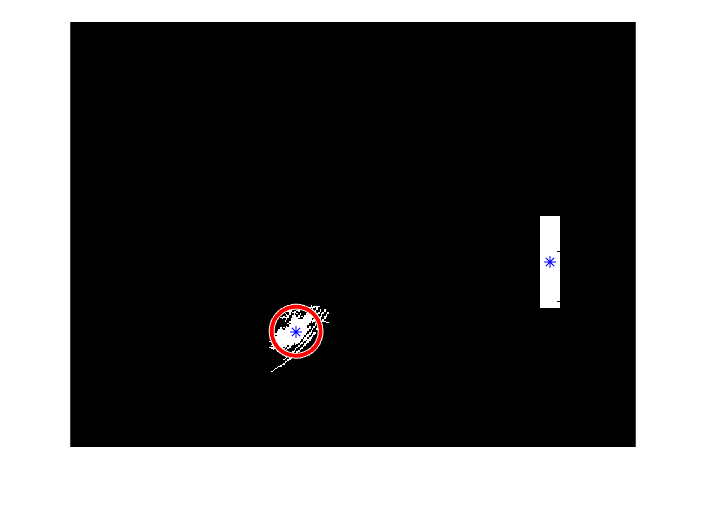

yyspec = r12;
imshow(yyspec)
[BW,maskedRGBImage] = createMask2(yyspec);  % create mask
FBW = imfill(BW,"holes");   % fill holes
BW2 = bwareaopen(FBW,500);  % remove smaller obj
BW_N = bwareafilt(BW2,2);  % retain N objects
stats = regionprops("table",BW_N,"Centroid", ...
    "MajorAxisLength","MinorAxisLength");
centroids = stats.Centroid;

imshow(BW_N)
hold on
plot(centroids(:,1),centroids(:,2),'b*')

diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;
%Plot the circles.

viscircles(centers(1,:),radii(1));
hold off


disp(['The radius of the cluster in reci-12dBFS is ' num2str(radii(1))])

The radius of the cluster in reci-12dBFS is 37.8193


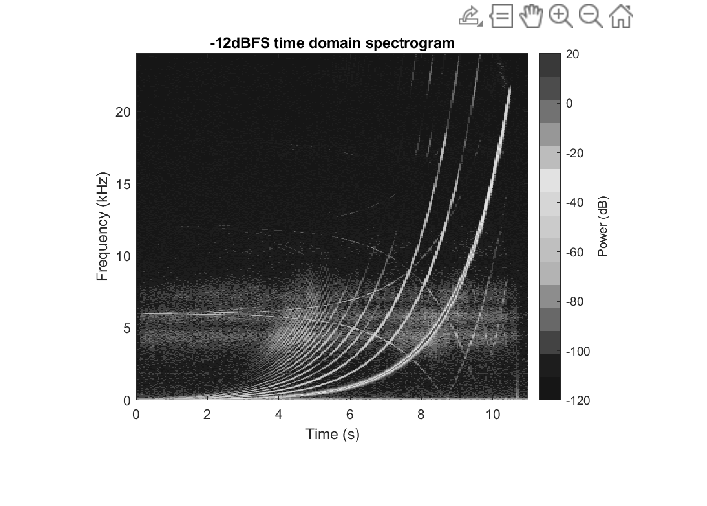

Ispec = rgb2gray(yyspec);
Out = double(Ispec).* double(BW_N);
imshow(Ispec)

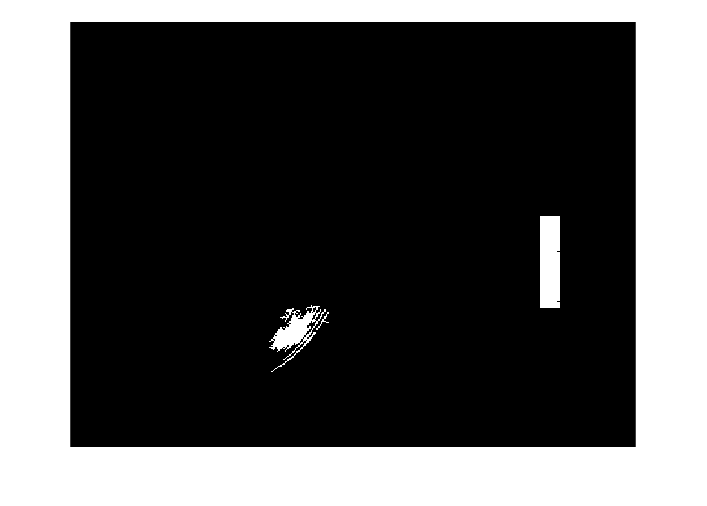

imshow(Out*0.5)

yy = y(:,3);  % -9dbfs
yys = yy(100000:300000);

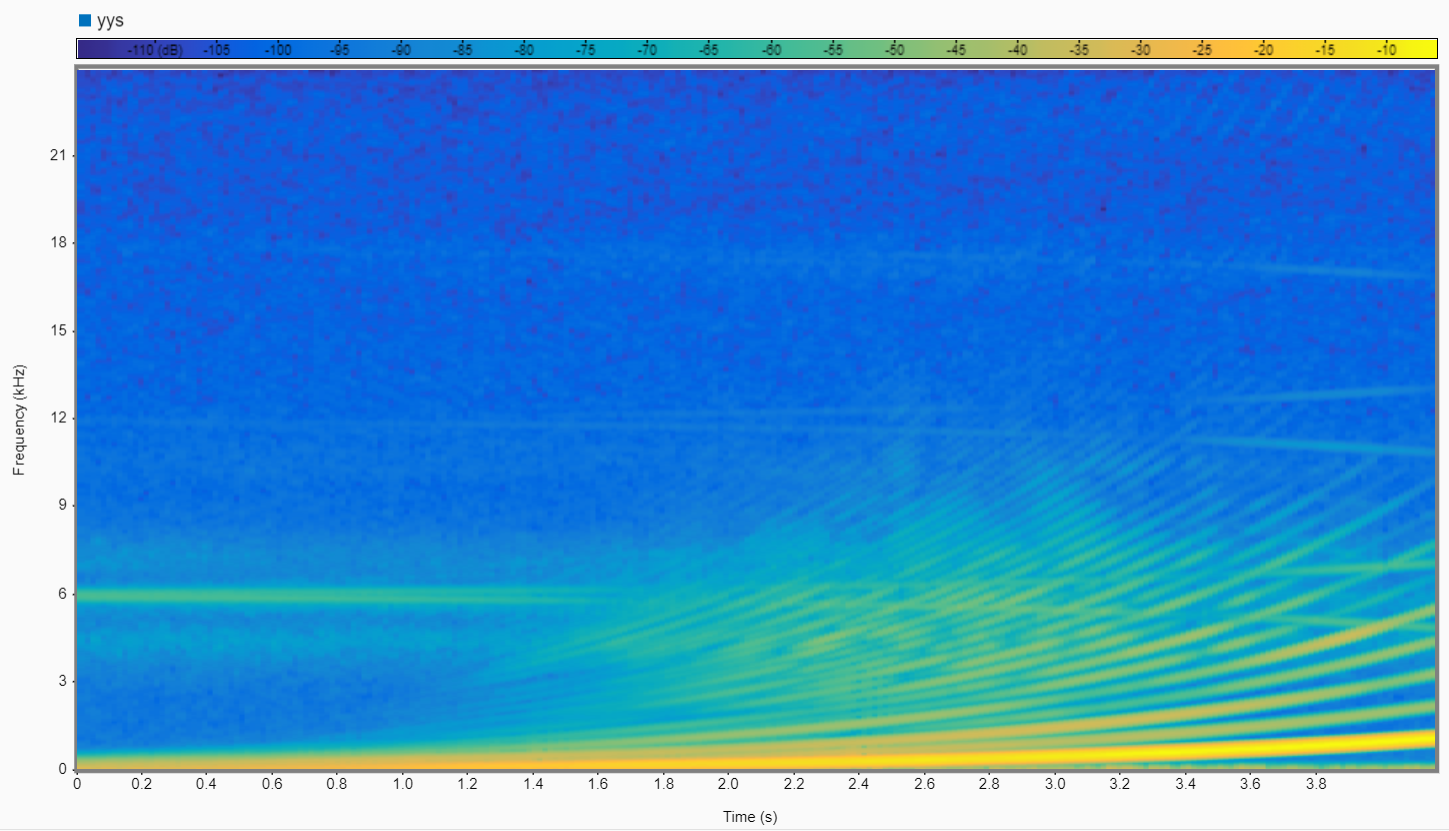

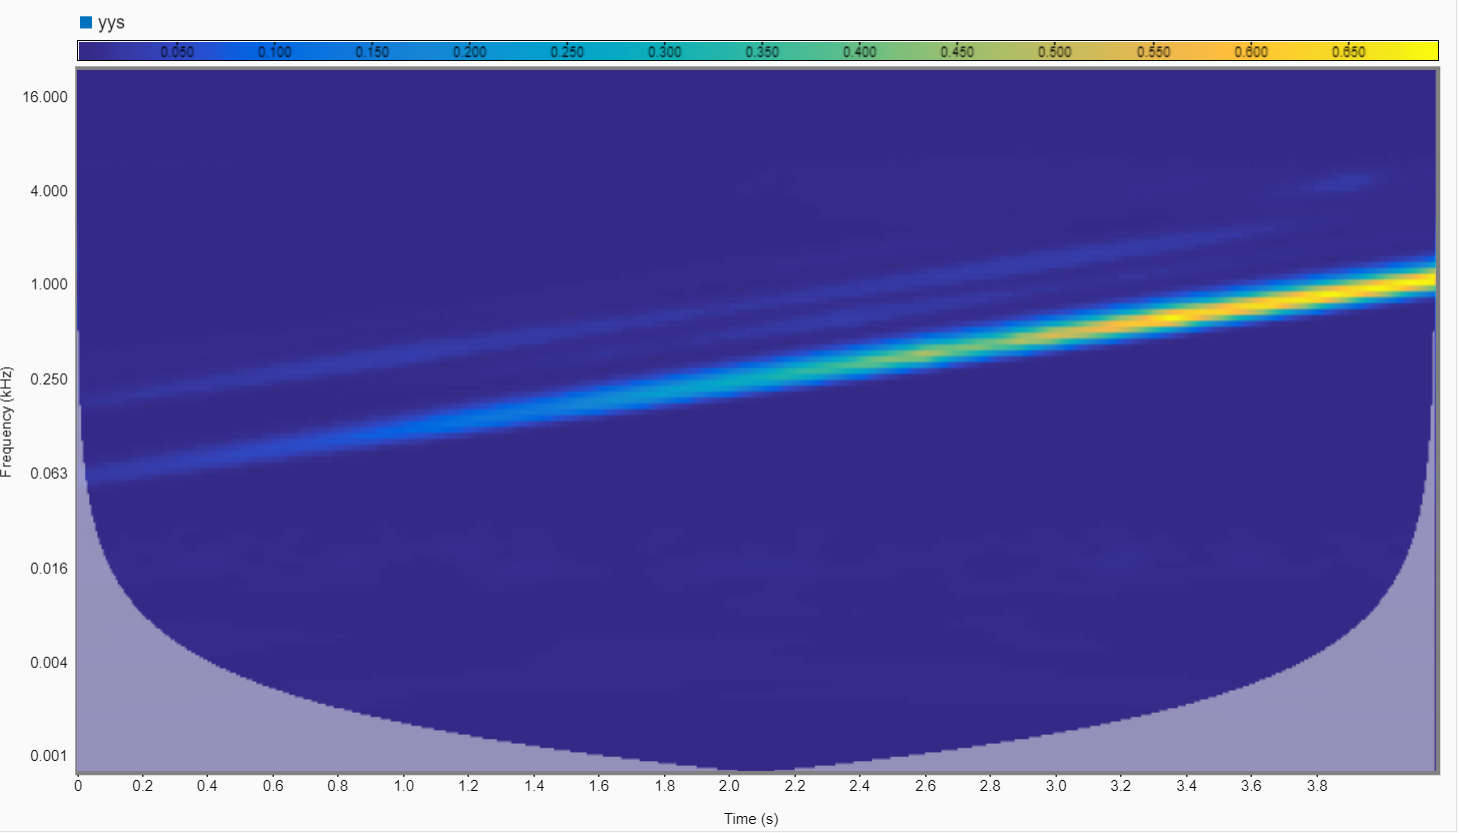


yy3 = y(:,3);  % -9dbfs
yys3 = yy3(100000:300000);
yy4 = y(:,4);  % -6dbfs
yys4 = yy4(100000:300000);

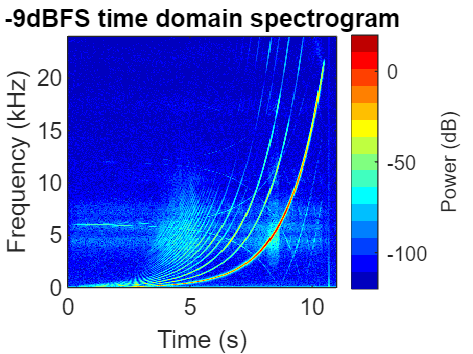

k = 3;    
spectrogram(yy3,hann(n,"periodic"),n/2,n,fs,'yaxis','power')
    colormap(jet(15))
    set(gca,'CLim',[-120 20])
    xlim([0 11])
    title(td(k)+ " time domain spectrogram")

    filename = "reci" + td(k) + ".png";

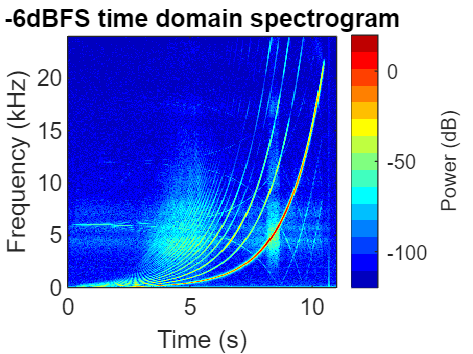

k = 4;
    spectrogram(yy4,hann(n,"periodic"),n/2,n,fs,'yaxis','power')
    colormap(jet(15))
    set(gca,'CLim',[-120 20])
    xlim([0 11])
    title(td(k)+ " time domain spectrogram")

    filename = "reci" + td(k) + ".png";